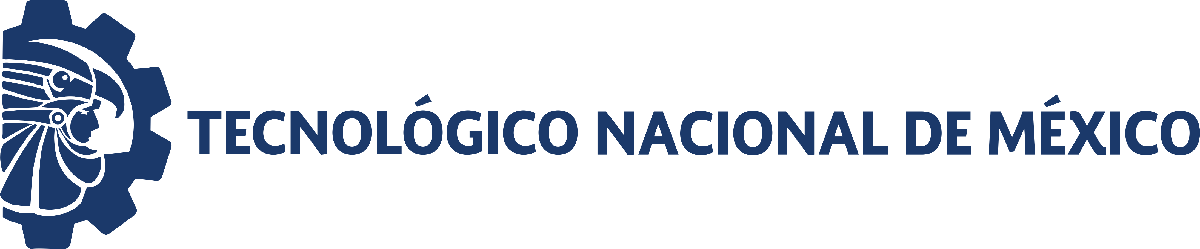                                 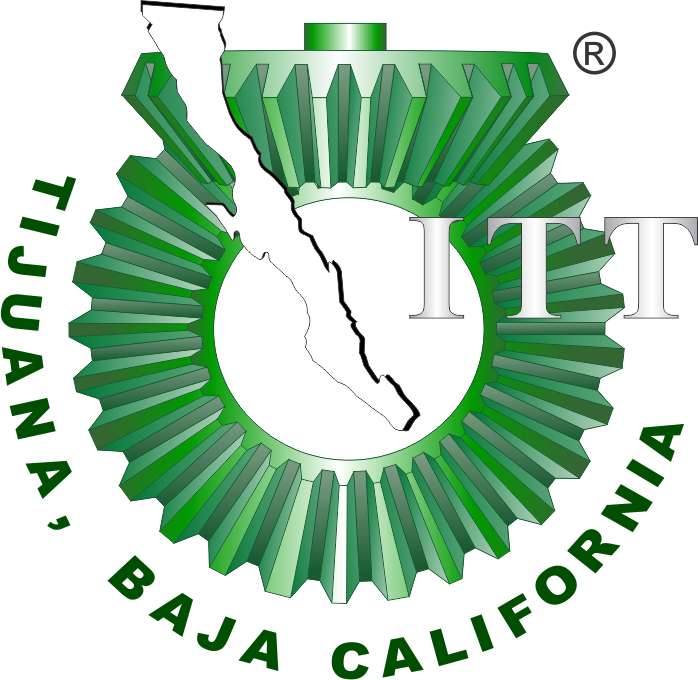

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

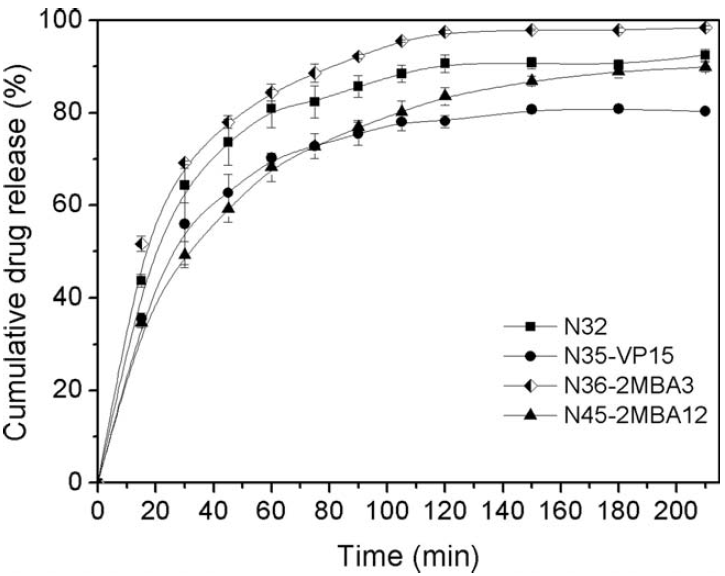

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $x\left(t\right)=\rho_1 \sqrt{t}-\rho_2 \;t$

Eureqa EDO: $\dot{x} =\rho_1 -\rho_2 \;t$

## Datos experimentales

clc; clear; close all; warning('off','all')
[t,x1,x2,x3,x4] = getdata('data.csv');

    t [min]     N45       N32       N35       N36  
    _______    ______    ______    ______    ______

        0           0         0         0         0
       15      34.286    43.571    35.536    51.429
       30      49.107    64.286    55.714    69.107
       45       58.75    73.571    62.679    77.857
       60      68.214    80.893    70.179    84.286
       75      72.679    82.321    72.679    88.393
       90      76.786    85.536    75.536    92.321
      105      80.179    88.571    77.679    95.536
      120      83.571    90.714    78.214    97.679
      150      86.786    90.893    80.714    97.857
      180      88.929    90.357    80.714    97.857
      210      89.821      92.5    80.179    98.393



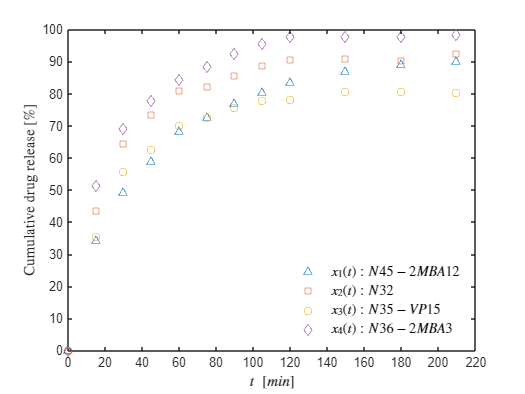

plotdata(t,x1,x2,x3,x4); exportgraphics(gcf,'data.pdf','ContentType','vector')

## Regresión no lineal, bioestadísticos y experimentación in silico

labels = {'x1(t): N45 - 2MBA12', 'x2(t) : N32','x3(t): N35 - VP15','x4(t): N36 - 2MBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Peppas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i=1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0;k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t): N45 - 2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        17.494       2.1742      4.8444     12.649     22.338    1.1196e-05
      {'n'}       0.31856     0.026465    0.058969    0.25959    0.37753    2.8384e-07

R-cuadrada ordinaria: 0.97953
Suma residual de cuadrados: 161.6982
Criterio de información de Akaike ajustado: 70.5978



    "Resultados para el Hidrogel: "    "x2(t) : N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.437       4.2808      9.5382     20.899     39.975    3.2559e-05
      {'n'}       0.22023     0.030434    0.067811    0.15242    0.28804    2.8029e-05

R-cuadrada ordinaria: 0.96319
Suma residual de cuadrados: 299.3451
Criterio de información de Akaike ajustado: 77.9881



    "Resultados para el Hidrogel: "    "x3(t): N35 - VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.771       3.8504      8.5793     16.191      33.35    7.5071e-05
      {'n'}       0.23562     0.033546    0.074745    0.16088    0.31037      3.61e-05

R-cuadrada ordinaria: 0.95778
Suma residual de cuadrados: 271.5986
Criterio de información de Akaike ajustado: 76.8209



    "Resultados para el Hidrogel: "    "x4(t): N36 - 2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}         34.11       3.8661      8.6143     25.495     42.724     4.947e-06
      {'n'}       0.21116     0.024566    0.054736    0.15642    0.26589    6.2448e-06

R-cuadrada ordinaria: 0.97493
Suma residual de cuadrados: 228.2449
Criterio de información de Akaike ajustado: 74.734



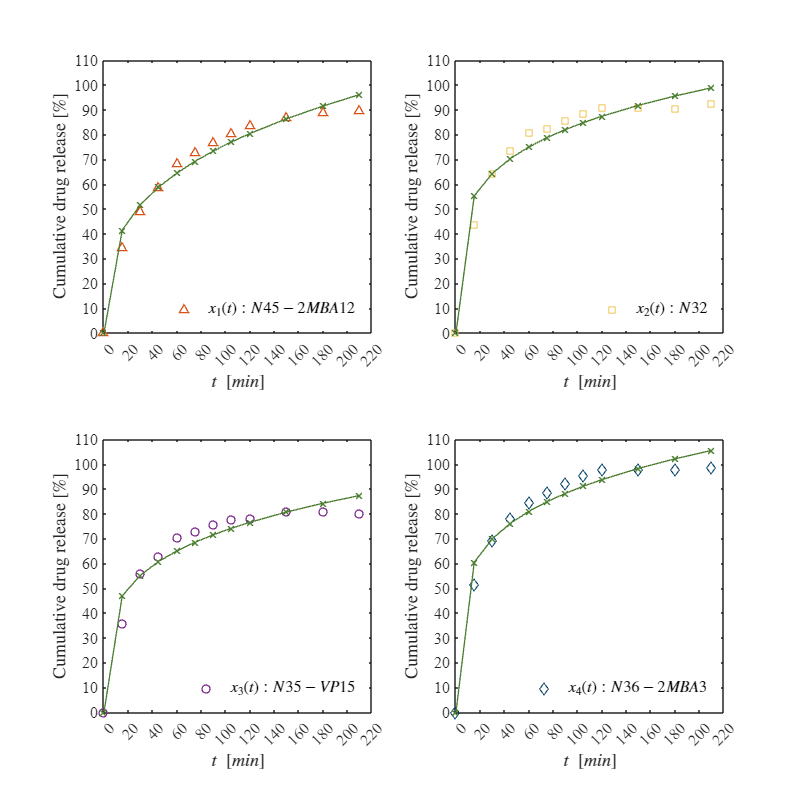

plotresults(t,xo,xp); exportgraphics(gcf,'peppas.pdf','ContentType','vector')

### Función farmacocinética de primer orden

beta0 = 100; k0 = 0.02; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ',string(labels(i))]);
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t): N45 - 2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'beta'}       87.839       1.4585      3.2497      84.589      91.088    3.8704e-14
     {'k'   }     0.025772    0.0015013    0.003345    0.022427    0.029117    9.4999e-09

R-cuadrada ordinaria: 0.99125
Suma residual de cuadrados: 69.1226
Criterio de información de Akaike ajustado: 60.3996



    "Resultados para el Hidrogel: "    "x2(t) : N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       89.986      0.83127       1.8522      88.134      91.838    1.1093e-16
     {'k'   }     0.040265    0.0017454    0.0038889    0.036376    0.044154    5.2915e-10

R-cuadrada ordinaria: 0.99532
Suma residual de cuadrados: 38.0524
Criterio de información de Akaike ajustado: 53.2365



    "Resultados para el Hidrogel: "    "x3(t): N35 - VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       79.443      0.64841       1.4448      77.998      80.888    3.2191e-17
     {'k'   }     0.037353    0.0013631    0.0030372    0.034316     0.04039    9.6997e-11

R-cuadrada ordinaria: 0.99665
Suma residual de cuadrados: 21.5605
Criterio de información de Akaike ajustado: 46.4193



    "Resultados para el Hidrogel: "    "x4(t): N36 - 2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       96.189       1.3643       3.0399      93.149      99.229    8.0357e-15
     {'k'   }     0.041754    0.0028444    0.0063377    0.035417    0.048092    4.3016e-08

R-cuadrada ordinaria: 0.98837
Suma residual de cuadrados: 105.8587
Criterio de información de Akaike ajustado: 65.5142



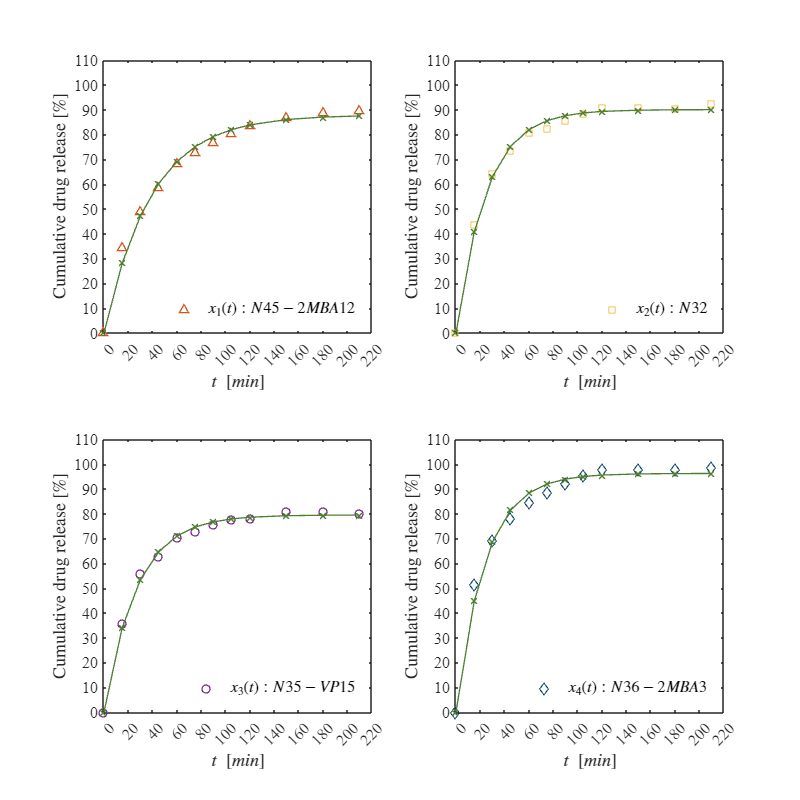

plotresults(t,xo,xfc); exportgraphics(gcf,'farmacocinética.pdf','ContentType','vector')

### Eureqa: Función del tiempo

rho1_0 = 11.6; 
rho2_0 = 0.372; 
xe1 = zeros(s(1),s(2));

for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = eureqafunction(t, xo(:,i), [rho1_0; rho2_0]);
    xe1(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t): N45 - 2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'rho_1'}      11.144      0.23899     0.53251     10.612     11.677    4.9583e-13
    {'rho_2'}      0.3333     0.020633    0.045973    0.28733    0.37927    1.7121e-08

R-cuadrada ordinaria: 0.99592
Suma residual de cuadrados: 32.2683
Criterio de información de Akaike ajustado: 51.258



    "Resultados para el Hidrogel: "    "x2(t) : N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'rho_1'}      14.544      0.26791     0.59693     13.947     15.141    1.0895e-13
    {'rho_2'}     0.57277     0.023129    0.051535    0.52124    0.62431    2.6345e-10

R-cuadrada ordinaria: 0.99501
Suma residual de cuadrados: 40.5476
Criterio de información de Akaike ajustado: 53.9987



    "Resultados para el Hidrogel: "    "x3(t): N35 - VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

    {'rho_1'}      12.484      0.27106     0.60397     11.88     13.088    5.6097e-13
    {'rho_2'}     0.47985     0.023402    0.052142    0.4277    0.53199    1.6817e-09

R-cuadrada ordinaria: 0.99355
Suma residual de cuadrados: 41.5088
Criterio de información de Akaike ajustado: 54.2799



    "Resultados para el Hidrogel: "    "x4(t): N36 - 2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'rho_1'}       15.71      0.12615     0.28107     15.429     15.991    2.7339e-17
    {'rho_2'}     0.62296     0.010891    0.024266    0.59869    0.64722    6.4708e-14

R-cuadrada ordinaria: 0.99901
Suma residual de cuadrados: 8.9897
Criterio de información de Akaike ajustado: 35.922



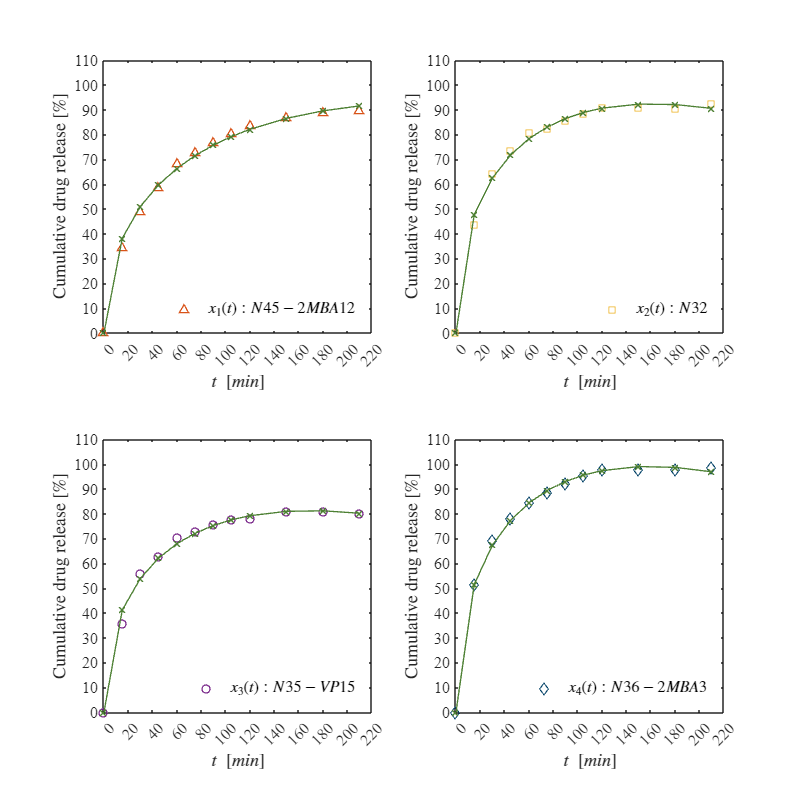

plotresults(t, xo, xe1); exportgraphics(gcf, 'eureqa.pdf', 'ContentType', 'vector')

### Eureqa: Farmacinética de primer orden

rho1_0 = 2.27; 
rho2_0 = 0.0257; 
xe2 = zeros(s(1),s(2));

for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = eureqaEDOfunction(t, xo(:,i), [rho1_0; rho2_0]);
    xe2(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t): N45 - 2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

    {'rho_1'}       2.2638      0.10607      0.23635      2.0275      2.5002    1.1366e-09
    {'rho_2'}     0.025772    0.0015013    0.0033451    0.022427    0.029117    9.5018e-09

R-cuadrada ordinaria: 0.99125
Suma residual de cuadrados: 69.1226
Criterio de información de Akaike ajustado: 60.3996



    "Resultados para el Hidrogel: "    "x2(t) : N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

    {'rho_1'}       3.6233      0.13864     0.30892      3.3144      3.9323    1.5491e-10
    {'rho_2'}     0.040265    0.0017454    0.003889    0.036376    0.044154     5.292e-10

R-cuadrada ordinaria: 0.99532
Suma residual de cuadrados: 38.0524
Criterio de información de Akaike ajustado: 53.2365



    "Resultados para el Hidrogel: "    "x3(t): N35 - VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

    {'rho_1'}       2.9674     0.094412      0.21036      2.7571      3.1778    2.4976e-11
    {'rho_2'}     0.037353    0.0013631    0.0030372    0.034316     0.04039    9.7007e-11

R-cuadrada ordinaria: 0.99665
Suma residual de cuadrados: 21.5605
Criterio de información de Akaike ajustado: 46.4193



    "Resultados para el Hidrogel: "    "x4(t): N36 - 2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

    {'rho_1'}       4.0163      0.24288      0.54116      3.4752      4.5575    1.3651e-08
    {'rho_2'}     0.041754    0.0028444    0.0063377    0.035417    0.048092    4.3021e-08

R-cuadrada ordinaria: 0.98837
Suma residual de cuadrados: 105.8587
Criterio de información de Akaike ajustado: 65.5142




plotresults(t, xo, xe2); exportgraphics(gcf, 'eureqaEDO.pdf', 'ContentType', 'vector')

## Funciones

### Datos experimentales

function [t, x1, x2, x3, x4] = getdata(filename)
    data = readmatrix(filename);

    t  = data(:, 1);
    x1 = data(:, 2);
    x2 = data(:, 3);
    x3 = data(:, 4);
    x4 = data(:, 5);
   
    T = table(t, x1, x2, x3, x4);
    T.Properties.VariableNames = {'t [min]', 'N45', 'N32', 'N35', 'N36'};
    disp(T);
end

function plotdata(t, x1, x2, x3, x4)
    figure; 
    hold on;  box on; grid off;
    
    plot(t, x1, '^', 'DisplayName', '$x_1(t) : N45 - 2MBA12$');
    plot(t, x2, 'square', 'DisplayName', '$x_2(t) : N32$');
    plot(t, x3, 'o', 'DisplayName', '$x_3(t) : N35 - VP15$');
    plot(t, x4, 'diamond', 'DisplayName', '$x_4(t) : N36 - 2MBA3$');
    
    xlim([0, 220]);
    ylim([0, 100]);
    xticks(0:20:220);
    yticks(0:10:100);

    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', 12);
    legend('Interpreter', 'latex', 'Location', 'southeast', 'Box', 'Off','FontSize', 11);    
end

### Modelos matemáticos y bioestadísticos

function mdl = peppas(to,xo,par)
    function x = model(par,t)
        k = par(1); n = par(2);
        x = k*t.^n;
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k';'n'};
    biostats(mdl,Parameters)
end

function biostats(mdl, Parameters)
  
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1 - alpha/2, dof);
    MoE = SE * tval;
    
    
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    
    disp(['Cantidad de datos: ', num2str(mdl.NumObservations)]);
    disp(['Cantidad de parámetros: ', num2str(mdl.NumCoefficients)]);
    disp(['Grados de libertad: ', num2str(dof)]);
    disp(['Valor t-student: ', num2str(tval)]);
    disp(['Alpha: ', num2str(alpha)]);
    disp(' '); 
    disp(Results);
    
   
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
 
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);
    fprintf(['\nCriterio de información de Akaike ajustado: ', num2str(AICc)]);
    fprintf('\n\n'); 
end

function plotresults(t,xo,xp)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 25])
    FS = 12;
    c1 = [0.8500, 0.3250, 0.0980];
    c2 = [0.9290, 0.6940, 0.1250];
    c3 = [0.4940, 0.1840, 0.5560];
    c4 = [0,0.25,0.4];
    c5 = [0.3,0.5,0.2];

    
    subplot(2,2,1); box on; hold on;
    plot(t, xo(:,1), '^', 'LineWidth', 1, 'Color', c1)
    plot(t, xp(:,1), '-x', 'LineWidth', 1, 'Color', c5)
    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', FS)
    L = legend('$x_1(t) : N45 - 2MBA12$');
    set(L, 'Interpreter', 'latex', 'FontSize', FS, 'Location', 'Southeast', ...
        'Box', 'Off', 'Orientation', 'Horizontal');
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(2,2,2); box on; hold on;
    plot(t, xo(:,2), 'square', 'LineWidth', 1, 'Color', c2)
    plot(t, xp(:,2), '-x', 'LineWidth', 1, 'Color', c5)
    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', FS)
    L = legend('$x_2(t) : N32$');
    set(L, 'Interpreter', 'latex', 'FontSize', FS, 'Location', 'Southeast', ...
        'Box', 'Off', 'Orientation', 'Horizontal');
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(2,2,3); box on; hold on;
    plot(t, xo(:,3), 'o', 'LineWidth', 1, 'Color', c3)
    plot(t, xp(:,3), '-x', 'LineWidth', 1, 'Color', c5)   
    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', FS)
    L = legend('$x_3(t) : N35 - VP15$');
    set(L, 'Interpreter', 'latex', 'FontSize', FS, 'Location', 'Southeast', ...
        'Box', 'Off', 'Orientation', 'Horizontal');
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(2,2,4); box on; hold on;
    plot(t, xo(:,4), 'diamond', 'LineWidth', 1, 'Color', c4)
    plot(t, xp(:,4), '-x', 'LineWidth', 1, 'Color', c5)
    xlabel('$t\ [min]$', 'Interpreter', 'latex', 'FontSize', FS)
    ylabel('Cumulative drug release [\%]', 'Interpreter', 'latex', 'FontSize', FS)
    L = legend('$x_4(t) : N36 - 2MBA3$');
    set(L, 'Interpreter', 'latex', 'FontSize', FS, 'Location', 'Southeast', ...
        'Box', 'Off', 'Orientation', 'Horizontal');
    xlim([0, 220]); ylim([0, 110]);
    xticks(0:20:220); yticks(0:10:110);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
end

function mdl = farmacocinetica(to, xo, par)  
    function x = model(par, t)
        beta = par(1);
        k = par(2);
        x = beta * (1 - exp(-k * t));
    end
    mdl = fitnlm(to, xo, @model, par);
    
    NombresParametros = {'beta'; 'k'}; 
    
    biostats(mdl, NombresParametros);
end

function mdl = eureqafunction(to, xo, par)
 
    function x = model(par, t)
        rho1 = par(1); 
        rho2 = par(2);
      
        x = (rho1 .* sqrt(t)) - (rho2 .* t);
    end

    mdl = fitnlm(to, xo, @model, par);
    NombresParametros = {'rho_1'; 'rho_2'};   
    biostats(mdl, NombresParametros);
end

function mdl = eureqaEDOfunction(to, xo, par)
    function fa = model(par, t)
        rho1 = par(1); 
        rho2 = par(2);
        
        dt = 0.1;
        time = (0:dt:max(t))'; 
        x = zeros(length(time), 1); 
        x(1) = 0; 
        n = round(max(t)/dt);

        %Método de Heun
        for i = 1:n 
            fx = rho1 - rho2 * x(i);
            xn = x(i) + fx * dt;
            fxn = rho1 - rho2 * xn;
            x(i+1) = x(i) + (fx + fxn) * dt / 2;
        end
        fa = interp1(time, x, t, 'linear');
    end

    mdl = fitnlm(to, xo, @model, par);
    NombresParametros = {'rho_1'; 'rho_2'};   
    biostats(mdl, NombresParametros);
end